% ------------------- VARIABLES PARAMETERS ------------------- %
efficiancy = 36;             % Efficiancy (electrical energy / thermal energy)[%]

mFuel = 142;                      % Mass of fuel [t]
e0U235 = 5;                    % Enrichment of U235 in UOX fuel [%]
e0Pu = 12;                     % Enrichment of Plutomium in MOX fuel [%]
FissileFissiblePu = 61.3;         %  Pourcentage of fissile Plutomium (Pu239) in MOX fuel [%]
UOXMOX = 75;                    % Pourcentage of UOX fuel [%]

V = 87;               % Volume of the core (m3)
T = 343;              % Temperatures in core (for moderator and neutrons speeds) [°C]
P = 154;               % Pressure in core (for moderator) [Bar]

moderator = "light water";                  % Material moderator 
ModFuel_ratio = 2.7;        % Volume of Moderator / Volume of Fuel <- at T0 and P0

Phi = 30.5*10^12;       % Neutron flux [cm-2.s-1]

cycleTime = 4;         % Time in reactors for fuel [Full Year Power]



% --------------------- FIXED PARAMETERS --------------------- %
stablesFP = 0.85;       % Pourcentage of stable fission product (others fission products are radioactive !)

kb = 8.6173303*10^-5;            % Boltzman contant [Ev/K]

muU235 = 2.42;              % Number of neutrons released after fission of U235
muU238 = 2.281;             % Number of neutrons released after fission of U238
muPu239 = 2.872;            % Number of neutrons released after fission of Pu239
muPu240 = 2.825;            % Number of neutrons released after fission of Pu240
muPu241 = 2.931;            % Number of neutrons released after fission of Pu241
muPu242 = 2.878;            % Number of neutrons released after fission of Pu242
muMa = 3.429;               % Number of neutrons released after fission of Ma   

EfU235 = 202.53 *1.85*10^-27;       % Energy released after fission of U235
EfU238 = 204.66 *1.85*10^-27;       % Energy released after fission of U238
EfPu239 = 207.02 *1.85*10^-27;      % Energy released after fission of Pu239
EfPu240 = 205.66 *1.85*10^-27;      % Energy released after fission of Pu240
EfPu241 = 210.73 *1.85*10^-27;      % Energy released after fission of Pu241
EfPu242 = 209.47 *1.85*10^-27;      % Energy released after fission of Pu242
EfMa = 210 *1.85*10^-27;            % Energy released after fission of Ma

RI0U235 = 413.4 *10^-24;
RI0U238 = 276.841 *10^-24;
RI0Pu239 = 480.7 *10^-24;
RI0Pu240 = 8510.13 *10^-24;
RI0Pu241 = 747.8 *10^-24;
RI0Pu242 = 1130.359 *10^-24;
RI0Ma = 1751.5 *10^-24;

mn = 1.6749*10^-27;              % neutron mass [kg]
mU235 = 3.933899*10^-28;         % U235 atom mass [t]
mU236 = 3.950648*10^-28;         % U236 atom mass [t]
mU238 = 3.984146*10^-28;         % U238 atom mass [t]
mPu239 = 4.000849*10^-28;        % Pu239 atom mass [t]
mPu240 = 4.017598*10^-28;        % Pu240 atom mass [t]
mPu241 = 4.034347*10^-28;        % Pu241 atom mass [t]
mPu242 = 4.051096*10^-28;        % Pu242 atom mass [t]
mMa = 4.067799*10^-28;           % Ma atom mass [t]
mFP = 1.958575*10^-28;           % FP atom mass [t]
mB10 = 1.662687*10^-29;          % B10 atom mass [t]

rhoB10 = 2.34;                  % Density of Boron 10 [g/cm3]
rhoU235 = 18.811;               % Density of U235 [g/cm3]
rhoU236 = 19.052;               % Density of U236 [g/cm3]
rhoU238 = 19.052;               % Density of U238 [g/cm3]
rhoPu239 = 19.4;                % Density of Pu239 [g/cm3]
rhoPu240 = 19.5;                % Density of Pu240 [g/cm3]
rhoPu241 = 19.6;                % Density of Pu241 [g/cm3]
rhoPu242 = 19.7;                % Density of Pu242 [g/cm3]
rhoMa = 13.3;                   % Volumic mass of Ma [g/cm3]
rhoFP = 8.755;                  % Volumic mass of FP [g/cm3]

cscB10F = 50 * 10^-24;                  % Fast capture cross section of B10 [barn]
cscB10Sd = 650 * 10^-24;                % Resonance capture cross section of B10 [barn]
cscB10T = 3837 * 10^-24;                % Thermal capture cross section of B10 [barn]

csfU235T = 585.1 *10^-24;               % Thermal fission cross section of U235 [barn]
csfU235Sd = 11 *10^-24;                 % Resonance fission cross section of U235 [barn]
csfU235F = 1.3 *10^-24;                 % Fast fission cross section of U235 [barn]
cscU235T = 98.71 *10^-24;               % Thermal capture cross section of U235 [barn]
cscU235Sd = 6 *10^-24;                  % Resonance capture cross section of U235 [barn]
cscU235F = 0.03 *10^-24;                % Fast capture cross section of U235 [barn]
cssU235 = 15.2 *10^-24;                 % Scattering cross section of U235 [barn]

csfU238T = 0.0000168 *10^-24;           % Thermal fission cross section of U238 [barn]
csfU238Sd = 0.000005 *10^-24;           % Resonance fission cross section of U238 [barn]
csfU238F = 0.5 *10^-24;                 % Fast fission cross section of U238 [barn]
cscU238T = 2.683 *10^-24;               % Thermal capture cross section of U238 [barn]
cscU238Sd = 0.2 *10^-24;                % Resonance capture cross section of U238 [barn]
cscU238F = 0.04 *10^-24;                % Fast capture cross section of U238 [barn]
cssU238 = 9.3 *10^-24;                  % Scattering cross section of U238 [barn]

csfPu239T = 747.4 *10^-24;
csfPu239Sd = 20 *10^-24;
csfPu239F = 2 *10^-24;
cscPu239T = 271.5 *10^-24;
cscPu239Sd = 4 *10^-24;
cscPu239F = 0.02 *10^-24;
cssPu239 = 8.813 *10^-24;

csfPu240T = 0.03621 *10^-24;
csfPu240Sd = 0.005 *10^-24;
csfPu240F = 1.8 *10^-24;
cscPu240T = 289.3 *10^-24;
cscPu240Sd = 15 *10^-24;
cscPu240F = 0.05 *10^-24;
cssPu240 = 2.667 *10^-24;

csfPu241T = 1012 *10^-24;
csfPu241Sd = 60 *10^-24;
csfPu241F = 1.9 *10^-24;
cscPu241T = 363.1 *10^-24;
cscPu241Sd = 10 *10^-24;
cscPu241F = 0.05 *10^-24;
cssPu241 = 11.26 *10^-24;

csfPu242T = 0.002436 *10^-24;
csfPu242Sd = 0.009 *10^-24;
csfPu242F = 1.5 *10^-24;
cscPu242T = 19.88 *10^-24;
cscPu242Sd = 8 *10^-24;
cscPu242F = 0.07 *10^-24;
cssPu242 = 8.326 *10^-24;

csfMaT = 587.4 *10^-24;         
csfMaSd = 85 *10^-24;
csfMaF = 2.5 *10^-24;
cscMaT = 131.4 *10^-24;
cscMaSd = 5 *10^-24;
cscMaF = 0.03 *10^-24;
cssMa = 8.853 *10^-24;

% ---------------------- COMPUTATIONS ---------------------- %
efficiancy = efficiancy/100;
e0U235 = e0U235/100;
e0Pu = e0Pu/100;
FissileFissiblePu = FissileFissiblePu/100;
UOXMOX = UOXMOX/100;
V=V*10^6;
T=T+273.15;
P=P*10^5;
cycleTime=cycleTime*365.2425*24*3600;

EkT = (3/2)*kb*T;                                       % average thermal neutrons kinetic Energy [eV]
vT = ((2*EkT*1.60218*10^-19)/mn)^0.5 *100;              % average thermal neutrons speed [cm/s];

if moderator == "light water"
    Edcmt = 0.920;                                  % Energy decrement of moderator
    cssMod = 64.505 *10^-24;                        % Scattering cross section of moderator [barn]
    cscModF = 0.0002 *10^-24;                       % Fast capture cross section of moderator [barn]
    cscModSd = 0.01005 *10^-24;                     % Resonance capture cross section of moderator [barn]
    cscModT = 0.6641899 *(220007/vT)*10^-24;        % Thermal capture cross section of moderator [barn]
    RI0Mod = 0.2990734 *10^-24;
    rhoMod0 = 0.998;
    Mmod = 18;
    ThExp = 30.15*10^-4;
    BModulus = 2.2*10^9;
elseif moderator == "heavy water"
    Edcmt = 0.509;                         
    cssMod = 12.4567 *10^-24;                 
    cscModF = 0.00021 *10^-24;              
    cscModSd = 0.00015 *10^-24;             
    cscModT = 0.0012899*(220007/vT)*10^-24; 
    RI0Mod = 0.0012334 *10^-24;
    rhoMod0 = 1.1056;
    Mmod = 20;
    ThExp = 2.15*10^-4;
    BModulus = 2.1*10^9;
elseif moderator == "graphite"
    Edcmt = 0.158;                         
    cssMod = 4.947 *10^-24;                 
    cscModF = 0.00002 *10^-24;              
    cscModSd = 0.0005 *10^-24;             
    cscModT = 0.00386*(220007/vT)*10^-24; 
    RI0Mod = 0.001885 *10^-24;
    rhoMod0 = 2.2;
    Mmod = 12;
    ThExp = 28.3*10^-6;
    BModulus = 33*10^9;
elseif moderator == "beryllium"
    Edcmt = 0.207;                         
    cssMod = 6.503 *10^-24;                 
    cscModF = 0.000001 *10^-24;              
    cscModSd = 0.0001 *10^-24;             
    cscModT = 0.00849*(220007/vT)*10^-24; 
    RI0Mod = 0.003822 *10^-24;
    rhoMod0 = 1.8477;
    Mmod = 9;
    ThExp = 12*10^-6;
    BModulus = 130*10^9;
elseif moderator == "none"
    Edcmt = 0.008;                         
    cssMod = 0;                 
    cscModF = 0;              
    cscModSd = 0;             
    cscModT = 0; 
    RI0Mod = 0;
    rhoMod0 = 1;
end
if moderator == "none"
    NMod = 0;
    rhoMod = 1;
else
    rhoMod = (rhoMod0/((1+ThExp*(T-293.15))*(1-((P-101325)/BModulus))));
    NMod = ModFuel_ratio*rhoMod*(6.02214076*10^23/Mmod);                                   % density of moderator'atoms [atoms/cm3] (T0 = 20°C)
end


EkF = 2*10^6;
vF = ((2*EkF*1.60218*10^-19)/mn)^0.5 *100;  
ns = log(6.242*10^18*0.5*mn*(vF*0.01)^2/EkT)/Edcmt;
vSd = vF*exp(-0.5*Edcmt*((ns-1)/log(ns)));


% 1 / v law :
csfU235T = csfU235T*(220007/vT);
cscU235T = cscU235T*(220007/vT);

csfU238T = csfU238T*(220007/vT);
cscU238T = cscU238T*(220007/vT);

csfPu239T = csfPu239T*(220007/vT);
cscPu239T = cscPu239T*(220007/vT);

csfPu240T = csfPu240T*(220007/vT);
cscPu240T = cscPu240T*(220007/vT);

csfPu241T = csfPu241T*(220007/vT);
cscPu241T = cscPu241T*(220007/vT);

csfPu242T = csfPu242T*(220007/vT);
cscPu242T = cscPu242T*(220007/vT);

csfMaT = csfMaT*(220007/vT);         
cscMaT = cscMaT*(220007/vT);


N0U235 = UOXMOX*(e0U235*mFuel/mU235)/V;
N0U238 = (UOXMOX*((1-e0U235)+(1-UOXMOX)*(1-e0Pu))*(mFuel/mU238)/V);
N0Pu239 = (1-UOXMOX)*(e0Pu*FissileFissiblePu*mFuel/mPu239)/V;
N0Pu240 = (1-UOXMOX)*(e0Pu*(1-FissileFissiblePu)*mFuel/mPu240)/V;


p = exp(-(1/Edcmt)*(((cscU235Sd+csfU235Sd)*N0U235+(cscU238Sd+csfU238Sd)*N0U238+(cscPu239Sd+csfPu239Sd)*N0Pu239+(cscPu240Sd+csfPu240Sd)*N0Pu240+cscModSd*NMod)/((cscU235Sd+csfU235Sd+cssU235)*N0U235+(cscU238Sd+csfU238Sd+cssU238)*N0U238+(cscPu239Sd+csfPu239Sd+cssPu239)*N0Pu239+(cscPu240Sd+csfPu240Sd+cssPu240)*N0Pu240+(cscModSd+cssMod)*NMod))*log(EkF/EkT));
SfisF = muU235*csfU235F*N0U235+muU238*csfU238F*N0U238+muPu239*csfPu239F*N0Pu239+muPu240*csfPu240F*N0Pu240;
SfisSd = muU235*csfU235Sd*N0U235+muU238*csfU238Sd*N0U238+muPu239*csfPu239Sd*N0Pu239+muPu240*csfPu240Sd*N0Pu240;
SfisT = muU235*csfU235T*N0U235+muU238*csfU238T*N0U238+muPu239*csfPu239T*N0Pu239+muPu240*csfPu240T*N0Pu240;
AbsF = (cscU235F+csfU235F)*N0U235+(cscU238F+csfU238F)*N0U238+(cscPu239F+csfPu239F)*N0Pu239+(cscPu240F+csfPu240F)*N0Pu240;
SctF = cssU235*N0U235+cssU238*N0U238+cssPu239*N0Pu239+cssPu240*N0Pu240+cssMod*NMod;
AbsSd = (cscU235Sd+csfU235Sd)*N0U235+(cscU238Sd+csfU238Sd)*N0U238+(cscPu239Sd+csfPu239Sd)*N0Pu239+(cscPu240Sd+csfPu240Sd)*N0Pu240;
SctSd = p*(cssU235*N0U235+cssU238*N0U238+cssPu239*N0Pu239+cssPu240*N0Pu240+cssMod*NMod);
AbsT = (cscU235T+csfU235T)*N0U235+(cscU238T+csfU238T)*N0U238+(cscPu239T+csfPu239T)*N0Pu239+(cscPu240T+csfPu240T)*N0Pu240;




PhiF = ((AbsT)*(AbsSd + SctSd)*(Phi*SctF^2*SctSd^2 + AbsT*Phi*SctF*SctSd^2 + AbsT*Phi*SctF^2*SctSd + AbsT*AbsSd*Phi*SctF*SctSd))/(SctF*SctSd*(AbsT^2*AbsSd^2 + 2*AbsT^2*AbsSd*SctSd + AbsT^2*SctF^2 + AbsT^2*SctSd^2 + SctF^2*SctSd^2));
PhiSd = ((AbsT)*(Phi*SctF^2*SctSd^2 + AbsT*Phi*SctF*SctSd^2 + AbsT*Phi*SctF^2*SctSd + AbsT*AbsSd*Phi*SctF*SctSd))/(SctSd*(AbsT^2*AbsSd^2 + 2*AbsT^2*AbsSd*SctSd + AbsT^2*SctF^2 + AbsT^2*SctSd^2 + SctF^2*SctSd^2));
PhiT = (Phi*SctF^2*SctSd^2 + AbsT*Phi*SctF*SctSd^2 + AbsT*Phi*SctF^2*SctSd + AbsT*AbsSd*Phi*SctF*SctSd)/(AbsT^2*AbsSd^2 + 2*AbsT^2*AbsSd*SctSd + AbsT^2*SctF^2 + AbsT^2*SctSd^2 + SctF^2*SctSd^2);


t=[0:3600*24:cycleTime];

aU235 = PhiF*(cscU235F+csfU235F) + PhiT*(cscU235T+csfU235T) + PhiSd*(cscU235Sd+csfU235Sd);
aU238 = PhiF*(cscU238F+csfU238F) + PhiT*(cscU238T+csfU238T) + PhiSd*(cscU238Sd+csfU238Sd);
aPu239 = PhiF*(cscPu239F+csfPu239F) + PhiT*(cscPu239T+csfPu239T) + PhiSd*(cscPu239Sd+csfPu239Sd);
aPu240 = PhiF*(cscPu240F+csfPu240F) + PhiT*(cscPu240T+csfPu240T) + PhiSd*(cscPu240Sd+csfPu240Sd);
aPu241 = PhiF*(cscPu241F+csfPu241F) + PhiT*(cscPu241T+csfPu241T) + PhiSd*(cscPu241Sd+csfPu241Sd);
aPu242 = PhiF*(cscPu242F+csfPu242F) + PhiT*(cscPu242T+csfPu242T) + PhiSd*(cscPu242Sd+csfPu242Sd);
aMa = PhiF*(cscMaF+csfMaF) + PhiT*(cscMaT+csfMaT) + PhiSd*(cscMaSd+csfMaSd);

cU235 = PhiF*cscU235F + PhiT*cscU235T + PhiSd*cscU235Sd;
cU238 = PhiF*cscU238F + PhiT*cscU238T + PhiSd*cscU238Sd;
cPu239 = PhiF*cscPu239F + PhiT*cscPu239T + PhiSd*cscPu239Sd;
cPu240 = PhiF*cscPu240F + PhiT*cscPu240T + PhiSd*cscPu240Sd;
cPu241 = PhiF*cscPu241F + PhiT*cscPu241T + PhiSd*cscPu241Sd;
cPu242 = PhiF*cscPu242F + PhiT*cscPu242T + PhiSd*cscPu242Sd;
cMa = PhiF*cscMaF + PhiT*cscMaT + PhiSd*cscMaSd;

fU235 = PhiF*csfU235F + PhiT*csfU235T + PhiSd*csfU235Sd;
fU238 = PhiF*csfU238F + PhiT*csfU238T + PhiSd*csfU238Sd;
fPu239 = PhiF*csfPu239F + PhiT*csfPu239T + PhiSd*csfPu239Sd;
fPu240 = PhiF*csfPu240F + PhiT*csfPu240T + PhiSd*csfPu240Sd;
fPu241 = PhiF*csfPu241F + PhiT*csfPu241T + PhiSd*csfPu241Sd;
fPu242 = PhiF*csfPu242F + PhiT*csfPu242T + PhiSd*csfPu242Sd;
fMa = PhiF*csfMaF + PhiT*csfMaT + PhiSd*csfMaSd;

NU235 = N0U235*exp(-t*aU235);

NU236 = N0U235*(cU235/aU235)*(1-exp(-t*aU235));

NU238 = N0U238*exp(-t*aU238);  

A1 = N0U238*(cU238/(aU238-aPu239));
NPu239 = A1*(exp(-t*aPu239)-exp(-t*aU238))+N0Pu239*exp(-t*aPu239);

B1 = A1*(cPu239/(aPu240-aU238));
B2 = (A1+N0Pu239)*(cPu239/(aPu239-aPu240));
NPu240 = B1*(exp(-t*aPu240)-exp(-t*aU238))+B2*(exp(-t*aPu240)-exp(-t*aPu239))+N0Pu240*exp(-t*aPu240);

C1 = B1*(cPu240/(aPu241-aU238));
C2 = B2*(cPu240/(aPu239-aPu241));
C3 = (B1+B2+N0Pu240)*(cPu240/(aPu240-aPu241));
NPu241 = C1*(exp(-t*aPu241)-exp(-t*aU238))+C2*(exp(-t*aPu239)-exp(-t*aPu241))+C3*(exp(-t*aPu241)-exp(-t*aPu240));

D1 = C1*(cPu241/(aPu242-aU238));
D2 = C2*(cPu241/(aPu239-aPu242));
D3 = C3*(cPu241/(aPu240-aPu242));
D4 = (C1-C2+C3)*(cPu241/(aPu241-aPu242));
NPu242 = D1*(exp(-t*aPu242)-exp(-t*aU238))+D2*(exp(-t*aPu242)-exp(-t*aPu239))+D3*(exp(-t*aPu240)-exp(-t*aPu242))+D4*(exp(-t*aPu242)-exp(-t*aPu241));

E1 = D1*(cPu242/(aU238-fMa));
E2 = D2*(cPu242/(aPu239-fMa));
E3 = D3*(cPu242/(aPu240-fMa));
E4 = D4*(cPu242/(aPu241-fMa));
E5 = (D1+D2-D3+D4)*(cPu242/(aPu242-fMa));
NMa = E1*(exp(-t*aU238)-exp(-t*fMa))+E2*(exp(-t*aPu239)-exp(-t*fMa))+E3*(exp(-t*fMa)-exp(-t*aPu240))+E4*(exp(-t*aPu241)-exp(-t*fMa))+E5*(exp(-t*fMa)-exp(-t*aPu242));

RfU235 = (N0U235*fU235)/aU235 - (N0U235*fU235*exp(-aU235*t))/aU235;
RfU238 = (N0U238*fU238)/aU238 - (N0U238*fU238*exp(-aU238*t))/aU238;
RfPu239 = fPu239*((A1 + N0Pu239)/aPu239 - A1/aU238) - fPu239*((exp(-aPu239*t)*(A1 + N0Pu239))/aPu239 - (A1*exp(-aU238*t))/aU238);
RfPu240 = fPu240*((B2*exp(-aPu239*t))/aPu239 - (exp(-aPu240*t)*(B1 + B2 + N0Pu240))/aPu240 + (B1*exp(-aU238*t))/aU238) - fPu240*(B2/aPu239 - (B1 + B2 + N0Pu240)/aPu240 + B1/aU238);
RfPu241 = fPu241*(C2/aPu239 - C3/aPu240 - C1/aU238 + (C1 - C2 + C3)/aPu241) - fPu241*((exp(-aPu241*t)*(C1 - C2 + C3))/aPu241 + (C2*exp(-aPu239*t))/aPu239 - (C3*exp(-aPu240*t))/aPu240 - (C1*exp(-aU238*t))/aU238);
RfPu242 = fPu242*((D2*exp(-aPu239*t))/aPu239 - (exp(-aPu242*t)*(D1 + D2 - D3 + D4))/aPu242 - (D3*exp(-aPu240*t))/aPu240 + (D4*exp(-aPu241*t))/aPu241 + (D1*exp(-aU238*t))/aU238) - fPu242*(D2/aPu239 - D3/aPu240 + D4/aPu241 + D1/aU238 - (D1 + D2 - D3 + D4)/aPu242);
RfMa = fMa*((exp(-fMa*t)*(E1 + E2 - E3 + E4 - E5))/fMa - (E2*exp(-aPu239*t))/aPu239 + (E3*exp(-aPu240*t))/aPu240 - (E4*exp(-aPu241*t))/aPu241 + (E5*exp(-aPu242*t))/aPu242 - (E1*exp(-aU238*t))/aU238) + fMa*(E2/aPu239 - E3/aPu240 + E4/aPu241 - E5/aPu242 + E1/aU238 - (E1 + E2 - E3 + E4 - E5)/fMa);

NFPstable = stablesFP*2*(RfU235 + RfU238 + RfPu239 + RfPu240 + RfPu241 + RfPu242 + RfMa);  
NFPradioactive = (1-stablesFP)*2*(RfU235 + RfU238 + RfPu239 + RfPu240 + RfPu241 + RfPu242 + RfMa);

RRfU235 = fU235*NU235;
RRfU238 = fU238*NU238;
RRfPu239 = fPu239*NPu239;
RRfPu240 = fPu240*NPu240;
RRfPu241 = fPu241*NPu241;
RRfPu242 = fPu242*NPu242;
RRfMa = fMa*NMa;

mU235Total = NU235*mU235*V;
mU236Total = NU236*mU236*V;
mU238Total = NU238*mU238*V;
mPu239Total = NPu239*mPu239*V;
mPu240Total = NPu240*mPu240*V;
mPu241Total = NPu241*mPu241*V;
mPu242Total = NPu242*mPu242*V;
mMaTotal = NMa*mMa*V;
mFPstableTotal = NFPstable*mFP*V;
mFPradioactiveTotal = NFPradioactive*mFP*V;
mfuelTotal = mU235Total+mU238Total+mPu239Total+mPu240Total+mPu241Total+mPu242Total+mMaTotal+mFPstableTotal+mFPradioactiveTotal;


SfisF = muU235*csfU235F*NU235+muU238*csfU238F*NU238+muPu239*csfPu239F*NPu239+muPu240*csfPu240F*NPu240+muPu241*csfPu241F*NPu241+muPu242*csfPu242F*NPu242+muMa*csfMaF*NMa;
SfisSd = muU235*csfU235Sd*NU235+muU238*csfU238Sd*NU238+muPu239*csfPu239Sd*NPu239+muPu240*csfPu240Sd*NPu240+muPu241*csfPu241Sd*NPu241+muPu242*csfPu242Sd*NPu242+muMa*csfMaSd*NMa;
SfisT = muU235*csfU235T*NU235+muU238*csfU238T*NU238+muPu239*csfPu239T*NPu239+muPu240*csfPu240T*NPu240+muPu241*csfPu241T*NPu241+muPu242*csfPu242T*NPu242+muMa*csfMaT*NMa;
AbsF = (cscU235F+csfU235F)*NU235+(cscU238F+csfU238F)*NU238+cscModF*NMod+(cscPu239F+csfPu239F)*NPu239+(cscPu240F+csfPu240F)*NPu240+(cscPu241F+csfPu241F)*NPu241+(cscPu242F+csfPu242F)*NPu242+(cscMaF+csfMaF)*NMa;
SctF = cssU235*NU235+cssU238*NU238+cssMod*NMod+cssPu239*NPu239+cssPu240*NPu240+cssPu241*NPu241+cssPu242*NPu242+cssMa*NMa;
AbsSd = (cscU235Sd+csfU235Sd)*NU235+(cscU238Sd+csfU238Sd)*NU238+cscModSd*NMod+(cscPu239Sd+csfPu239Sd)*NPu239+(cscPu240Sd+csfPu240Sd)*NPu240+(cscPu241Sd+csfPu241Sd)*NPu241+(cscPu242Sd+csfPu242Sd)*NPu242+(cscMaSd+csfMaSd)*NMa;
p = exp(-(1/Edcmt)*(((cscU235Sd+csfU235Sd)*NU235+(cscU238Sd+csfU238Sd)*NU238+cscModSd*NMod+(cscPu239Sd+csfPu239Sd)*NPu239+(cscPu240Sd+csfPu240Sd)*NPu240+(cscPu241Sd+csfPu241Sd)*NPu241+(cscPu242Sd+csfPu242Sd)*NPu242+(cscMaSd+csfMaSd)*NMa)./((cscU235Sd+csfU235Sd+cssU235)*NU235+(cscU238Sd+csfU238Sd+cssU238)*NU238+(cscModSd+cssMod)*NMod+(cscPu239Sd+csfPu239Sd+cssPu239)*NPu239+(cscPu240Sd+csfPu240Sd+cssPu240)*NPu240+(cscPu241Sd+csfPu241Sd+cssPu241)*NPu241+(cscPu242Sd+csfPu242Sd+cssPu242)*NPu242+(cscMaSd+csfMaSd+cssMa)*NMa))*log(EkF/EkT));
SctSd = p.*(cssU235*NU235+cssU238*NU238+cssPu239*NPu239+cssPu240*NPu240+cssPu241*NPu241+cssPu242*NPu242+cssMa*NMa+cssMod*NMod);
AbsT = (cscU235T+csfU235T)*NU235+(cscU238T+csfU238T)*NU238+cscModT*NMod+(cscPu239T+csfPu239T)*NPu239+(cscPu240T+csfPu240T)*NPu240+(cscPu241T+csfPu241T)*NPu241+(cscPu242T+csfPu242T)*NPu242+(cscMaT+csfMaT)*NMa;

dNFdt = (SfisF-AbsF-SctF)*PhiF + SfisSd*PhiSd + SfisT*PhiT;
dNSddt = SctF*PhiF - (AbsSd+SctSd)*PhiSd;
dNTdt = SctSd*PhiSd - AbsT*PhiT;

NB10F = zeros(1,length(t));
NB10Sd = zeros(1,length(t));
NB10T = zeros(1,length(t));
SextF = zeros(1,length(t));
SextSd = zeros(1,length(t));
SextT = zeros(1,length(t));
for i = 1:length(t)
    if dNFdt(i) >= 0
        NB10F(i) = (SfisSd(i)*PhiSd + SfisT(i)*PhiT + (SfisF(i)-AbsF(i)-SctF(i))*PhiF)/(PhiF*cscB10F);
        SextF(i) = 0;
    else
        NB10F(i) = 0;
        SextF(i) = -((SfisF(i)-AbsF(i)-SctF(i))*PhiF + SfisSd(i)*PhiSd + SfisT(i)*PhiT);
    end

    if dNSddt(i) >= 0
        NB10Sd(i) = (SctF(i)*PhiF - (AbsSd(i)+SctSd(i))*PhiSd)/(PhiSd*cscB10Sd);
        SextSd(i) = 0;
    else
        NB10Sd(i) = 0;
        SextSd(i) = -(SctF(i)*PhiF - (AbsSd(i)+SctSd(i))*PhiSd);
    end

    if dNTdt(i) >= 0
        NB10T(i) = (SctSd(i)*PhiSd - AbsT(i)*PhiT)/(PhiT*cscB10T);
        SextT(i) = 0;
    else
        NB10T(i) = 0;
        SextT(i) = -(SctSd(i)*PhiSd - AbsT(i)*PhiT);
    end
end
NB10 = (NB10T+NB10Sd+NB10F);
Sext = SextT+SextSd+SextF;

mCr = NB10*V*mB10;
VCr = 10^6*mCr/rhoB10;     % [cm3]

Vfuel = 10^6*((mU235Total/rhoU235)+(mU236Total/rhoU236)+(mU238Total/rhoU238)+(mPu239Total/rhoPu239)+(mPu240Total/rhoPu240)+(mPu241Total/rhoPu241)+(mPu242Total/rhoPu242)+(mMaTotal/rhoMa)+(mFPstableTotal+mFPradioactiveTotal/rhoFP));     % Volume of fuel [cm3]
Vmod = Vfuel*ModFuel_ratio*rhoMod0/rhoMod;

BU = (RfU235*EfU235+RfU238*EfU238+RfPu239*EfPu239+RfPu240*EfPu240+RfPu241*EfPu241+RfPu242*EfPu242+RfMa*EfMa)*V/mFuel;
Eth = (RRfU235*EfU235+RRfU238*EfU238+RRfPu239*EfPu239+RRfPu240*EfPu240+RRfPu241*EfPu241+RRfPu242*EfPu242+RRfMa*EfMa)*V*24*3600*24;  % Thermal energy per day [GWh]
PowerTh = 1000*Eth/24;           
PowerElec = PowerTh*efficiancy;
PowerElecMean = mean(PowerElec);

PhiT    % [Thermal neutrons /cm2/s]

PhiT = 3.2807e+13

PhiSd   % [Resonance neutrons /cm2/s]

PhiSd = 1.3195e+12

PhiF    % [Fast neutrons /cm2/s]

PhiF = 1.2716e+12


NT = PhiT/vT        % Number of thermal neutrons per cm3

NT = 8.4044e+07

NSd = PhiSd/vSd     % Number of resonance neutrons per cm3

NSd = 1.0670e+04

NF = PhiF/vF        % Number of fast neutrons per cm3

NF = 650.0764

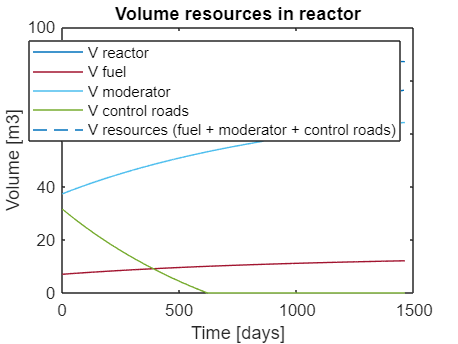


plot(V*ones(length(VCr),1)*10^-6, 'DisplayName','V reactor','Color','#0072BD');
hold on
plot(Vfuel*10^-6, 'DisplayName','V fuel','Color','#A2142F');
plot(Vmod*10^-6, 'DisplayName','V moderator','Color','#4DBEEE');
plot(VCr*10^-6, 'DisplayName','V control roads','Color','#77AC30');
plot((VCr+Vfuel+Vmod)*10^-6, 'DisplayName','V resources (fuel + moderator + control roads)','Color','#0072BD', 'LineStyle','--');
hold off
title('Volume resources in reactor')
xlabel('Time [days]')
ylabel('Volume [m3]')
legend

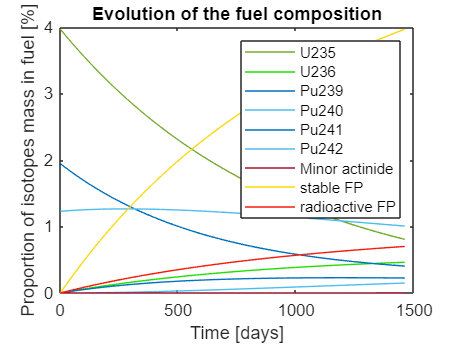


plot(100*mU235Total./mfuelTotal,'DisplayName','U235', 'Color', '#77AC30');
hold on
plot(100*mU236Total./mfuelTotal,'DisplayName','U236', 'Color', '#21DF04');
%plot(100*mU238Total./mfuelTotal,'DisplayName','U238', 'Color', '#77AC30');
plot(100*mPu239Total./mfuelTotal,'DisplayName','Pu239', 'Color', '#0072BD');
plot(100*mPu240Total./mfuelTotal,'DisplayName','Pu240', 'Color', '#4DBEEE');
plot(100*mPu241Total./mfuelTotal,'DisplayName','Pu241', 'Color', '#0072BD');
plot(100*mPu242Total./mfuelTotal,'DisplayName','Pu242', 'Color', '#4DBEEE');
plot(100*mMaTotal./mfuelTotal,'DisplayName','Minor actinide', 'Color', '#A2142F');
plot(100*mFPstableTotal./mfuelTotal,'DisplayName','stable FP', 'Color', '#F8D706');
plot(100*mFPradioactiveTotal./mfuelTotal,'DisplayName','radioactive FP', 'Color', '#F31D0A');
hold off
title('Evolution of the fuel composition')
xlabel('Time [days]')
ylabel('Proportion of isotopes mass in fuel [%]')
legend

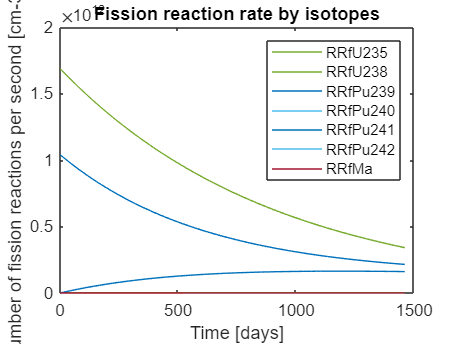


plot(RRfU235, 'DisplayName','RRfU235', 'Color', '#77AC30');
hold on
plot(RRfU238, 'DisplayName','RRfU238', 'Color', '#77AC30');
plot(RRfPu239, 'DisplayName','RRfPu239', 'Color', '#0072BD');
plot(RRfPu240, 'DisplayName','RRfPu240', 'Color', '#4DBEEE');
plot(RRfPu241, 'DisplayName','RRfPu241', 'Color', '#0072BD');
plot(RRfPu242, 'DisplayName','RRfPu242', 'Color', '#4DBEEE');
plot(RRfMa, 'DisplayName','RRfMa', 'Color', '#A2142F');
hold off
title('Fission reaction rate by isotopes')
xlabel('Time [days]')
ylabel('Number of fission reactions per second [cm-3.s-1]')
legend

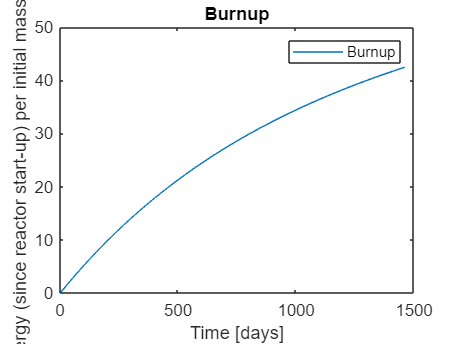



plot(BU, 'DisplayName', 'Burnup');
title('Burnup')
xlabel('Time [days]')
ylabel('Thermal energy (since reactor start-up) per initial mass of fuel [GWd/t]')
legend

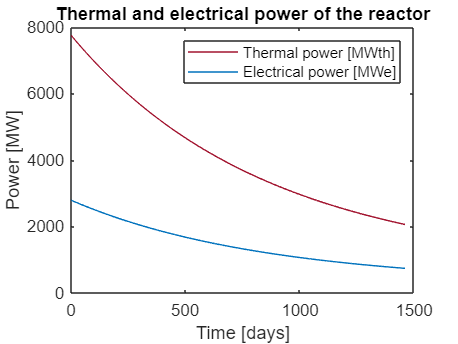


plot(PowerTh,'DisplayName','Thermal power [MWth]', 'Color', '#A2142F');
hold on
plot(PowerElec,'DisplayName','Electrical power [MWe]', 'Color', '#0072BD');
hold off
title('Thermal and electrical power of the reactor')
xlabel('Time [days]')
ylabel('Power [MW]')
legend

PowerElecMean

PowerElecMean = 1.4862e+03